# Waste Analysis Demo

Use the ThermoeconomicModel function to make waste analysis

### **Read and create the Thermoeconomic Model**

file='gturbo_model.xlsx';
model=ThermoeconomicTool(file);

ERROR: cStatusLogger. Table name ResourcesCost do not exists
INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [Reference] are valid
INFO: cDataModel. Exergy values [GEN97] are valid
INFO: cDataModel. Exergy values [ET79] are valid
INFO: cDataModel. Exergy values [EC79] are valid
INFO: cDataModel. Exergy values [ER78] are valid
INFO: cDataModel. Exergy values [T1050] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. No Resources Cost Data available
INFO: cDataModel. Data Model gturbo_model is valid
INFO: cThermoeconomicModel. Set Reference State: Reference
INFO: cThermoeconomicModel. Set State: Reference
INFO: cThermoeconomicModel. Compute Thermoeconomic Analysis for State: Reference


model.setDebug(false);

### Define Waste Parameters

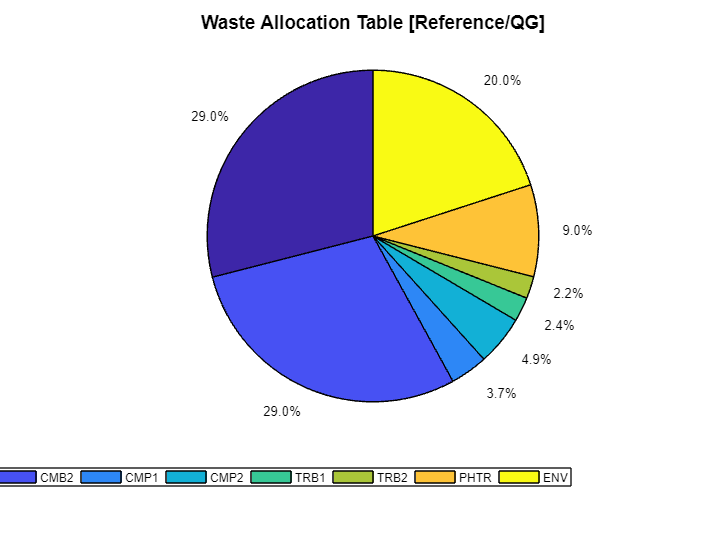

WasteFlows=convertCharsToStrings(model.WasteFlows);
WasteFlow=convertStringsToChars(WasteFlows(2));
model.setWasteType(WasteFlow,'IRREVERSIBILITY');
model.setWasteRecycled(WasteFlow,0.2);
model.graphWasteAllocation(WasteFlow);

### Compute Exergy Cost

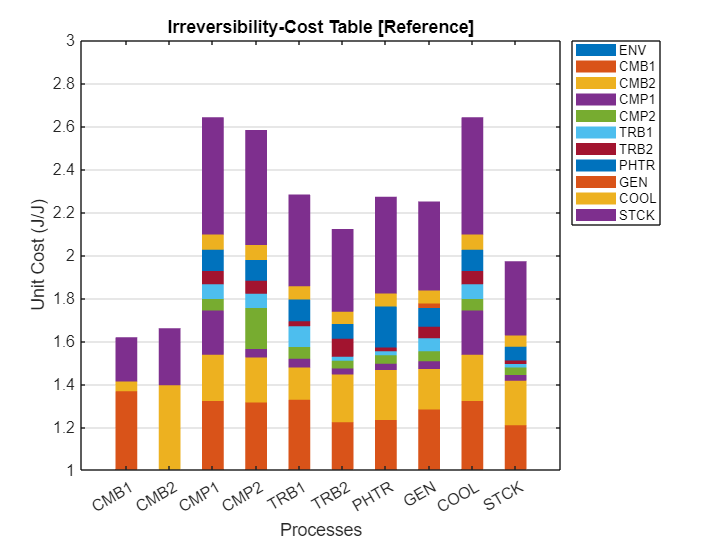

model.wasteAllocation;
graphCost(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

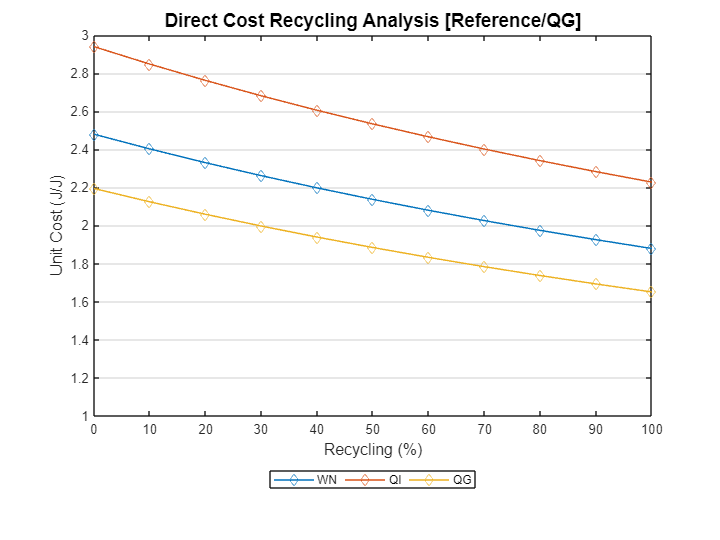

rad=model.recyclingAnalysis(WasteFlow);
rad.graphRecycling;

printResults(rad);

Direct Cost Recycling Analysis (J/J)

 Recycle (%)         WN        QI        QG
--------------------------------------------
      0          2.4792    2.9388    2.1942
     10          2.4020    2.8473    2.1243
     20          2.3296    2.7615    2.0588
     30          2.2615    2.6807    1.9971
     40          2.1973    2.6047    1.9391
     50          2.1368    2.5330    1.8843
     60          2.0796    2.4652    1.8326
     70          2.0255    2.4010    1.7836
     80          1.9742    2.3402    1.7371
     90          1.9255    2.2824    1.6931
    100          1.8792    2.2275    1.6512

